
clc;clear;close
tic

##   1. base de datos

-     en la clase 1 van los 1

-     en la clase 0 van los 0

### sonar

load('preprocesar\data\sonar.mat');
variables=1:60;
target=61;

clase1=sonarOrdenada(1:110,[variables target]);
clase0=sonarOrdenada(111:end,[variables target]);

### cancerMama

% load('cancerMama.mat')
% variables=1:30;
% target=31;
% clase0=Datos(1:354,[variables target]);%esta es en donde van los 1
% clase1=Datos(354:end,[variables target]);%esta es en donde van los 0

### ovarian cancer

% load('C:\Program Files\MATLAB\R2020a\toolbox\stats\statsdemos\ovariancancer.mat')
% obs(1:121,4001)=ones();
% obs(122:end,4001)=zeros();
% obs=double(obs);
% 
% variables=1:4000;
% target=4001;
% 
% clase1=obs(1:121,[variables target]);%esta es en donde van los 1
% clase0=obs(122:end,[variables target]);%esta es en donde van los 0

categories=variables;
ratings=[clase0(:,1:end-1);clase1(:,1:end-1)];
names=[clase0(:,end);clase1(:,end)];

w = 1./var(ratings);
[wcoeff,score,latent,tsquared,explained] = pca(ratings,'VariableWeights',w);

**Percent variance explained.**

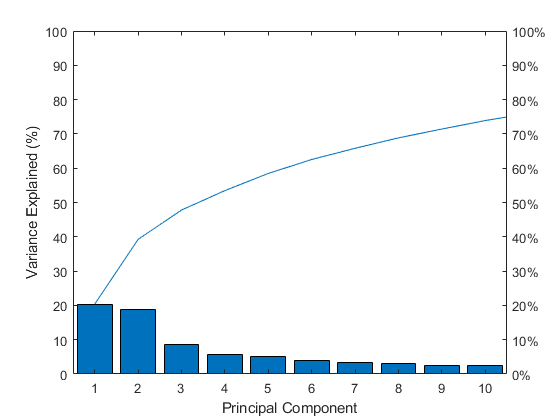

figure("Name","varianza acumulada")
pareto(explained(1:end,1))
xlabel('Principal Component')
ylabel('Variance Explained (%)')

este es el valor del que nos vamos a fijar observando su valor acumulado

explained

explained =    20.3749
   18.8792
    8.5481
    5.6707
    5.0059
    4.0588
    3.2698
    3.0422
    2.5626
    2.4875


acumulado=0

acumulado = 0


for i=1:length(explained)
    acumulado=explained(i)+acumulado;
    if acumulado>90
        break
    end
end

salida

variables=1:i

variables =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22
